Checklist:

1. Graficar Orientación en Y del teléfono y de SwingDAQ para que obtenga el tiempo de "offset" (diferencia en x de los picos). **[DONE]**

2. Ese tiempo de "offset" se aplica para todas sus gráficas que son todas de tiempo en el eje de x. **[DONE]**

3. Graficar Velocidad Angular en Y del teléfono y de Swing DAQ. Acuerdese que la velocidad angular en  SwingDAQ está en grados/s y debe convertir a rad/s antes de graficar. **[DONE]**

4.Calcular la Aceleracion Centrifugal, ac = OmegaY (rad/s) del SwingDAQ ^2 * h **[DONE]**

5. Calgular ac + gcos(OrientY en rad) y graficar comparando con aceleracion en z del SwingDAQ. Acuerdese que la aceleración en SwingDAQ está en m/s2. Si esta usando el Sistema Inglés debe cambiar esa aceleracion en in/s2. Puede utilizar g=386.4 in/s2. **[DONE]**

6. Calcular Tension en las cadenas graficando LC5 y LC6 contra el tiempo. Los resultados en los "Load Cells" estan en lb. Toda esta información de las unidades del SwinDAQ se encuentre en Moodle en la Seccion del Proyecto de Curso. **[DONE]**

7. Calibrar las fuerzas de LC5 y LC6 para que en la parte de cuando soltamos el peso (antes del movimiento), de un valor de 5 lb (22.24 N), respectivamente. Este factor de calibración lo debe utilizar cada vez que utilice LC5 y LC6.

8. Comparar la Tension (LC5 + LC6) vs la tension calculada usando el movimiento del columpio, aceleracion en z * (Weight/g).

9. Comparar el momento en flexion vertical de la viga utilizando las fuerzas de los "load cells" (LC1+LC2)d y el momento utilizando esta ecuacion: LC5*cos (OrientY (rad))(l-s)/2.10.  Comparar el momento en flexion horizontal de la viga utilizando las fuerzas de los "load cells" (LC1+LC3)d y el momento utilizando esta ecuacion: LC6*sin (OrientY (rad))(l-s)/2

11. Para los pasos 9 y 10 debe utlizar otro factor de calibracion para los "load cells" LC1, LC2 y LC3 como discutido en clase.  En este caso debe utilizar la parte de la grafica antes del movimiento para calibrar (LC1+LC2)d y LC5*cos(OrientY(rad))(l-s)/2.  Lo mismo sucede para (LC1+LC3)d y LC6*sin(OrientY(rad))(l-s)/2.

Laptop Data Units (SwingDAQ)

- Acceleration: m/s^2

- Orientation: Degrees -> Turned into rad

- Angular Velocity: degrees/s -> Turned into rad/s

- Forces: lb -> Turned into Newtons (N)

Phone Data Units

- Acceleration: m/s^2

- Orientation: Degrees -> Turned into rad

- Angular Velocity: rad/s

Load swingDAQ data

% Load Data
load swingdata.mat 

% If you want to write to excel, uncomment
% writetable(acquiredData, "swingdata.xlsx");

% Remove possible spikes from LC1 to LC6
LC1 = removespikes(acquiredData.LC1);
LC2 = removespikes(acquiredData.LC2);
LC3 = removespikes(acquiredData.LC3);
LC4 = removespikes(acquiredData.LC4);
LC5 = removespikes(acquiredData.LC5);
LC6 = removespikes(acquiredData.LC6);

% Convert to Newtons
acquiredData.LC1 = acquiredData.LC1 * 4.4482;
acquiredData.LC2 = acquiredData.LC2 * 4.4482;
acquiredData.LC3 = acquiredData.LC3 * 4.4482;
acquiredData.LC4 = acquiredData.LC4 * 4.4482;
acquiredData.LC5 = acquiredData.LC5 * 4.4482;
acquiredData.LC6 = acquiredData.LC6 * 4.4482;

% Angular Velocity from Laptop is in degrees/s
% Change to rad/s
acquiredData.OmegaX = acquiredData.OmegaX * (pi/180);
acquiredData.OmegaY = acquiredData.OmegaY * (pi/180);
acquiredData.OmegaZ = acquiredData.OmegaZ * (pi/180);

% Define the lenghts and heights of swingset (in meters)
w = 1.651 % 65 inches

w = 1.6510

H = 1.829 % 72 inches

H = 1.8290

l = 2.006 % 79 inches

l = 2.0060

h = 1.524 % 60 inches

h = 1.5240

s = 0.432 % 17 inches

s = 0.4320

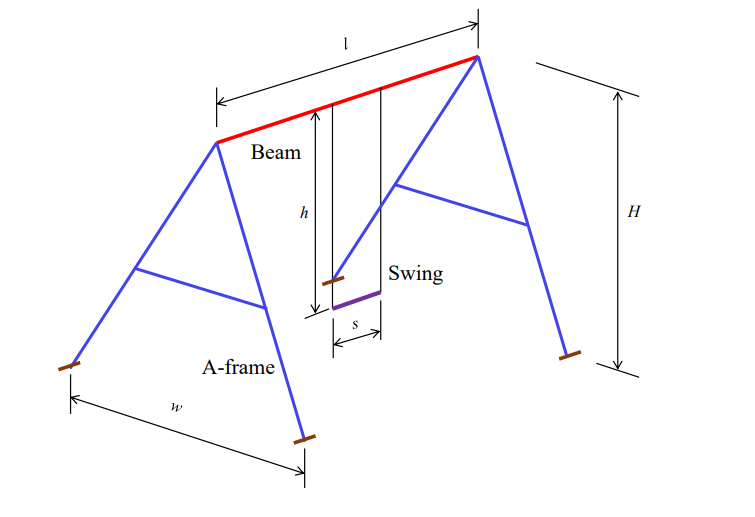

Load Phone Data

% Load Data
load phonedata.mat

Acceleration = renamevars(Acceleration, ["X","Y","Z"],...
["AccelX","AccelY","AccelZ"]);
AngularVelocity = renamevars(AngularVelocity, ["X","Y","Z"],...
["OmegaY","OmegaX","OmegaZ"]);
Orientation = renamevars(Orientation, ["X","Y","Z"],...
["OrientX","OrientY","OrientZ"]); % Note the switch in order
% because of naming convention in
% MATLAB Mobile/iphone

phoneData = synchronize(Acceleration, AngularVelocity, Orientation, ...
'union', 'linear'); % Merge the three timetables into one
% If want to write to Excel, uncomment
% writetimetable(phoneData,"phoneData.xlsx");

% Orientation from both datasets is in degrees
% Change to rad
acquiredData.OrientX = acquiredData.OrientX * (pi/180);
acquiredData.OrientY = acquiredData.OrientY * (pi/180);
acquiredData.OrientZ = acquiredData.OrientZ * (pi/180);
phoneData.OrientX = phoneData.OrientX * (pi/180);
phoneData.OrientY = phoneData.OrientY * (pi/180);
phoneData.OrientZ = phoneData.OrientZ * (pi/180);

% find index of each peak
%[~, idx1] = max(acquiredData.OrientY);
%[~, idx2] = max(phoneData.OrientY);
%toffset = acquiredData.Time(idx1) - phoneData.Time(idx2); % offset between swing and phone data obtained
% by comparing peaks in OrientY

%toffset = -17.677
%disp(toffset);
%t_phone = second(phoneData.Timestamp,"secondofday");
%t_phone = t_phone - t_phone(1)-toffset;

% Change timestamps from phone data to seconds
% We do this so it matches the laptop data better
phoneData.TimeOnly = timeofday(phoneData.Timestamp);
phoneData.TimeOnly.Format = 'hh:mm:ss.SSS';
initial_time = phoneData.TimeOnly(1);
phoneData.Time = phoneData.TimeOnly - initial_time;
phoneData = removevars(phoneData, 'TimeOnly');
time_seconds = seconds(phoneData.Time);
phoneData.Time = time_seconds;

clear Acceleration AngularVelocity Orientation

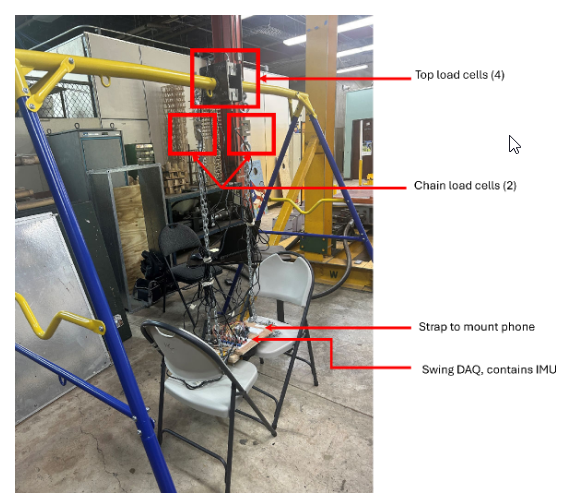

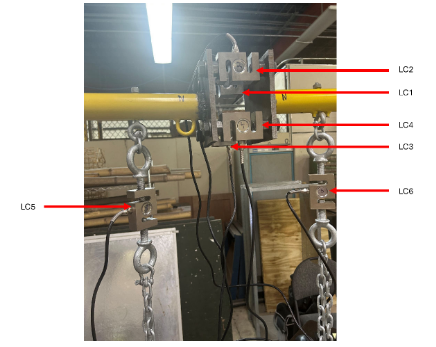

Purposes:

- IMU - Measure acceleration and angular velocity. Estimate orientation.

- LC5 & LC6 - Measure Chain Tension.

- LC1 through LC4 - Measure Beam Bending Moment.

What we need to measure from our datasets:

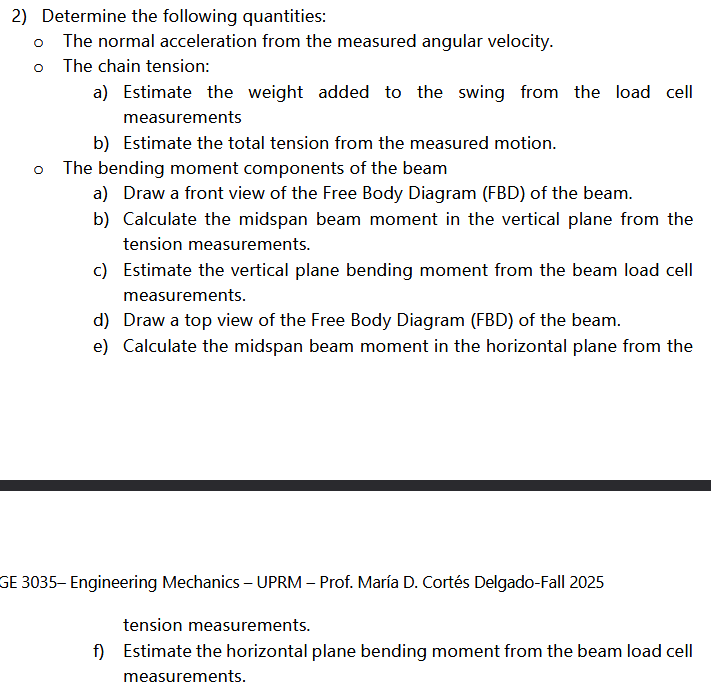

Calculate time offset between laptop and phone data

time_laptop = acquiredData.Time;
time_phone = phoneData.Time;
orient_y_laptop = acquiredData.OrientY;
orient_y_phone = phoneData.OrientY;

disp("Orientation Graphs to find time offset.")

Orientation Graphs to find time offset.


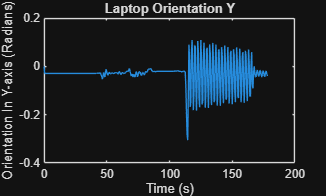

plot(time_laptop, orient_y_laptop);
title("Laptop Orientation Y");
ylabel("Orientation In Y-axis (Radians)");
xlabel("Time (s)");

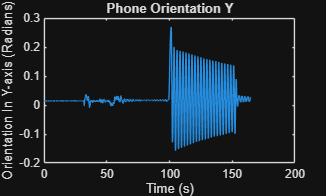

clear plot

plot(time_phone, orient_y_phone);
title("Phone Orientation Y");
ylabel("Orientation In Y-axis (Radians)");
xlabel("Time (s)");

clear plot

% Movement in Y Orientation of Laptop Data starts at X=114.502
% Movement in Y Orientation of Phone Data starts at X=101.171
% We can use this to calculate the offset time 
toffset = 114.502 - 101.171;
disp("Time Offset for phone data and graphs:")

Time Offset for phone data and graphs:


disp(toffset + " s");

13.331 s



phoneData.Time = phoneData.Time + toffset;
time_phone = phoneData.Time; % Update variable to include time with offsets

disp("Orientation Graphs with time offset applied.")

Orientation Graphs with time offset applied.


plot(time_laptop, orient_y_laptop);
title("Laptop Orientation Y");
ylabel("Orientation In Y-axis (Radians)");
xlabel("Time (s)");

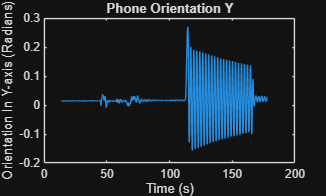

clear plot

plot(time_phone, orient_y_phone);
title("Phone Orientation Y");
ylabel("Orientation In Y-axis (Radians)");
xlabel("Time (s)");

clear plot

Calculate Normal Acceleration

% Calculate with data from both laptop and phone 
% Radius is equal to height of chains = 60 inches or 1.524 meters
r = h; % Set radius equal to height of chains

% Calculate average normal acceleration with laptop data
mag_omega_laptop = sqrt((acquiredData.OmegaX.^2) + (acquiredData.OmegaY.^2) + (acquiredData.OmegaZ.^2));
a_normal_laptop = (mag_omega_laptop.^2) * r;
avg_a_normal_laptop = mean(a_normal_laptop);
disp("Average Normal Acceleration using Laptop Data")

Average Normal Acceleration using Laptop Data


disp(avg_a_normal_laptop + " m/s^2");

0.071552 m/s^2



% Calculate average normal acceleration with phone data
mag_omega_phone = sqrt(phoneData.OmegaX.^2 + phoneData.OmegaY.^2 + phoneData.OmegaZ.^2);
a_normal_phone = (mag_omega_phone.^2) * r;
avg_a_normal_phone = mean(a_normal_phone);
disp("Average Normal Acceleration using Phone Data");

Average Normal Acceleration using Phone Data


disp(avg_a_normal_phone + " m/s^2");

0.0746 m/s^2


clear plot 

Graph Angular Velocity in Y from Laptop and Phone Data

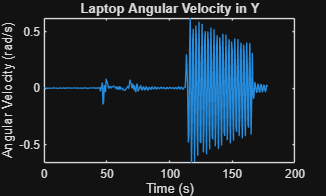

time = acquiredData.Time;
ang_vel_laptop_y = acquiredData.OmegaY;

plot(time, ang_vel_laptop_y);
title("Laptop Angular Velocity in Y");
xlabel("Time (s)");
ylabel("Angular Velocity (rad/s)");

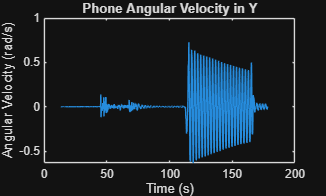

clear plot 

time = phoneData.Time;
ang_vel_phone_y = phoneData.OmegaY;
plot(time, ang_vel_phone_y);
title("Phone Angular Velocity in Y");
xlabel("Time (s)");
ylabel("Angular Velocity (rad/s)");

clear plot

Calculate Centrifugal Acceleration

% Height of swing chains = h
ac = (phoneData.OmegaY.^2) * h;
avg_ac = mean(ac);

disp("Average Centrifugal Acceleration using Phone Data");

Average Centrifugal Acceleration using Phone Data


disp(avg_ac + " m/s^2");

0.065237 m/s^2


Calculate ac + gcos(OrientY in rad) from phone and graph it. Compare it to angular acceleration Z from laptop.

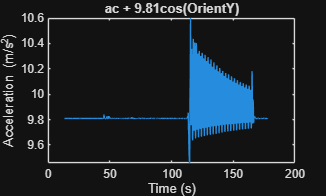

col = (ac + 9.81) .* cos(phoneData.OrientY);
phone_time = phoneData.Time;
laptop_time = acquiredData.Time;

plot(phone_time,col);
title("ac + 9.81cos(OrientY)");
xlabel("Time (s)");
ylabel("Acceleration (m/s^2)");

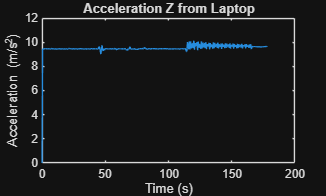

clear plot

plot(laptop_time,acquiredData.AccelZ);
title("Acceleration Z from Laptop");
xlabel("Time (s)");
ylabel("Acceleration (m/s^2)");

clear plot

disp("Mean value from formula: " + mean(col) + " m/s^2");

Mean value from formula: 9.8553 m/s^2


disp("Mean value from laptop acceleration z: " + mean(acquiredData.AccelZ) + " m/s^2");

Mean value from laptop acceleration z: 9.5036 m/s^2


Calculate Swing Weight and Chain Tensions

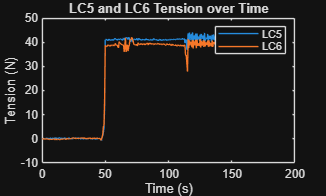

% Graph the force measurements from LC5 and LC6 for reference
% LC5 and LC6 are in between their chain connecting swing and beam
time = acquiredData.Time;
lc5_col = acquiredData.LC5;
plot(time,lc5_col);
hold on

lc6_col = acquiredData.LC6;
title("LC5 and LC6 Tension over Time");
xlabel('Time (s)');
ylabel('Tension (N)');
plot(time,lc6_col);
legend("LC5", "LC6")
hold off

clear plot

% Between both chains:
% While swing is still on the platform, F = ma -> F ~ -0.66 N
% After swing is suspended on the air, F = ma -> F ~ 39.82 N
platform_f = -0.66; % We could say it's 0 too
suspended_f = 39.82;
delta_f = suspended_f - platform_f;
disp("Chain Tension when swing is on the platform: " + platform_f + " N");

Chain Tension when swing is on the platform: -0.66 N


disp("Chain Tension when swing is suspended mid-air: " + suspended_f + " N");

Chain Tension when swing is suspended mid-air: 39.82 N


disp(" ");


% This difference corresponds to the force that the chains must supply to lift 
% the swing off the platform, which is effectively the weight of the swing.
% We only account for static calculations. mass = DeltaF / g
weight_mass = delta_f / 9.81;
disp("Mass of the swing");

Mass of the swing


disp(weight_mass + " kg");

4.1264 kg



% We can calculate the weight of the swing now
% W = mg
weight_swing = weight_mass * 9.81;
disp("Weight of the swing");

Weight of the swing


disp(weight_swing + " N");

40.48 N


disp(" ");


% Calibrate LC5 and LC6